# `Tutorial on CPS Control`

clear;
clc;

choose a system from the following

system = "acc"

system = "acc"

### Continuous-time System : Automotatic Cruise Control

if system == "acc"
Aa = [0 1;
      0 0];
Bb = [0;
      1];
Cc = [1 0];
Dd = 0;
acc = ss(Aa,Bb,Cc,Dd);
sys_ss = acc;
x0 = [10;1]; % initial state
Ts = 0.1;
ref = 90; % reference to be tracked
end

### Continuous-time System : DC Motor Speed Control

if system == "dcmotor"
J = 0.01;
b = 0.01;
K = 0.01;
R = 1;
L = 0.5;
Aa = [-b/J   K/J
    -K/L   -R/L];
Bb = [0
    1/L];
Cc = [1   0];
Dd = 0;
dcmotor = ss(Aa,Bb,Cc,Dd);
sys_ss = acc;
x0 = [0.1;1]; % initial state
Ts= 0.1;
ref = 1;
end

### Discretisation of the System

choose time horizon to plot on

time = 20;

Choosing a sampling period (seconds)

sys_d = c2d(sys_ss,Ts,'zoh');

A = sys_d.a;
B = sys_d.b;
C = sys_d.c;
D = sys_d.d;

plot_vectorx1=zeros(1,time);
plot_vectorx2=zeros(1,time);

## Open Loop System

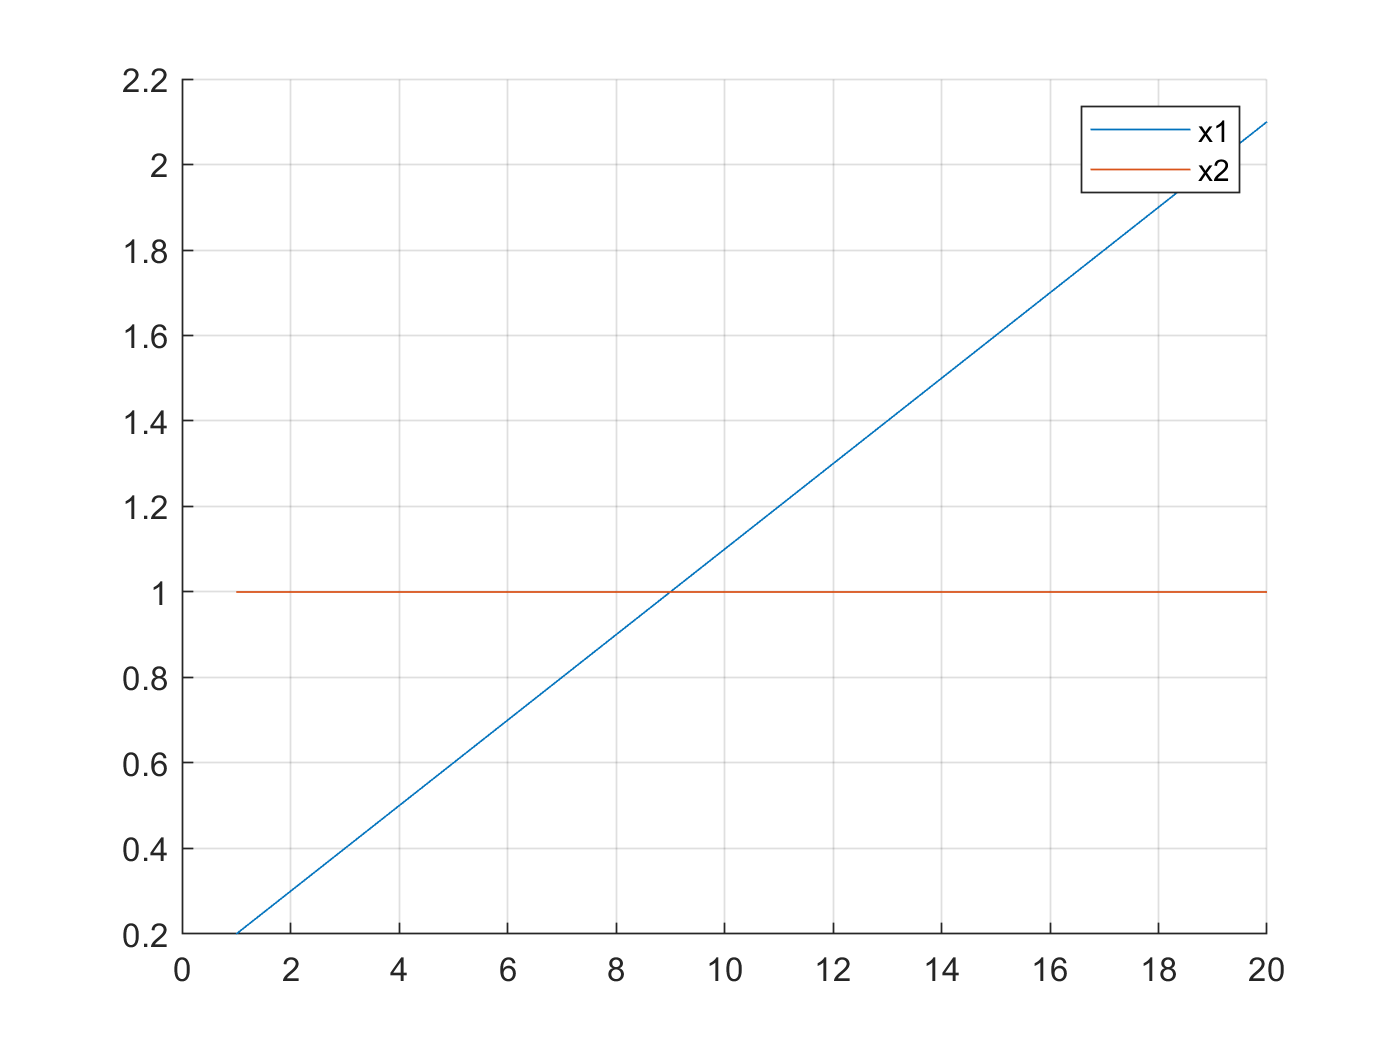

% x = [0.1;1];
x = x0;
for i=1:time
    x = A*x;
    plot_vectorx1(i) = x(1);
    plot_vectorx2(i) = x(2);
end
clf
hold on
plot(plot_vectorx1);
plot(plot_vectorx2);
legend({'x1','x2'});
grid on
hold off

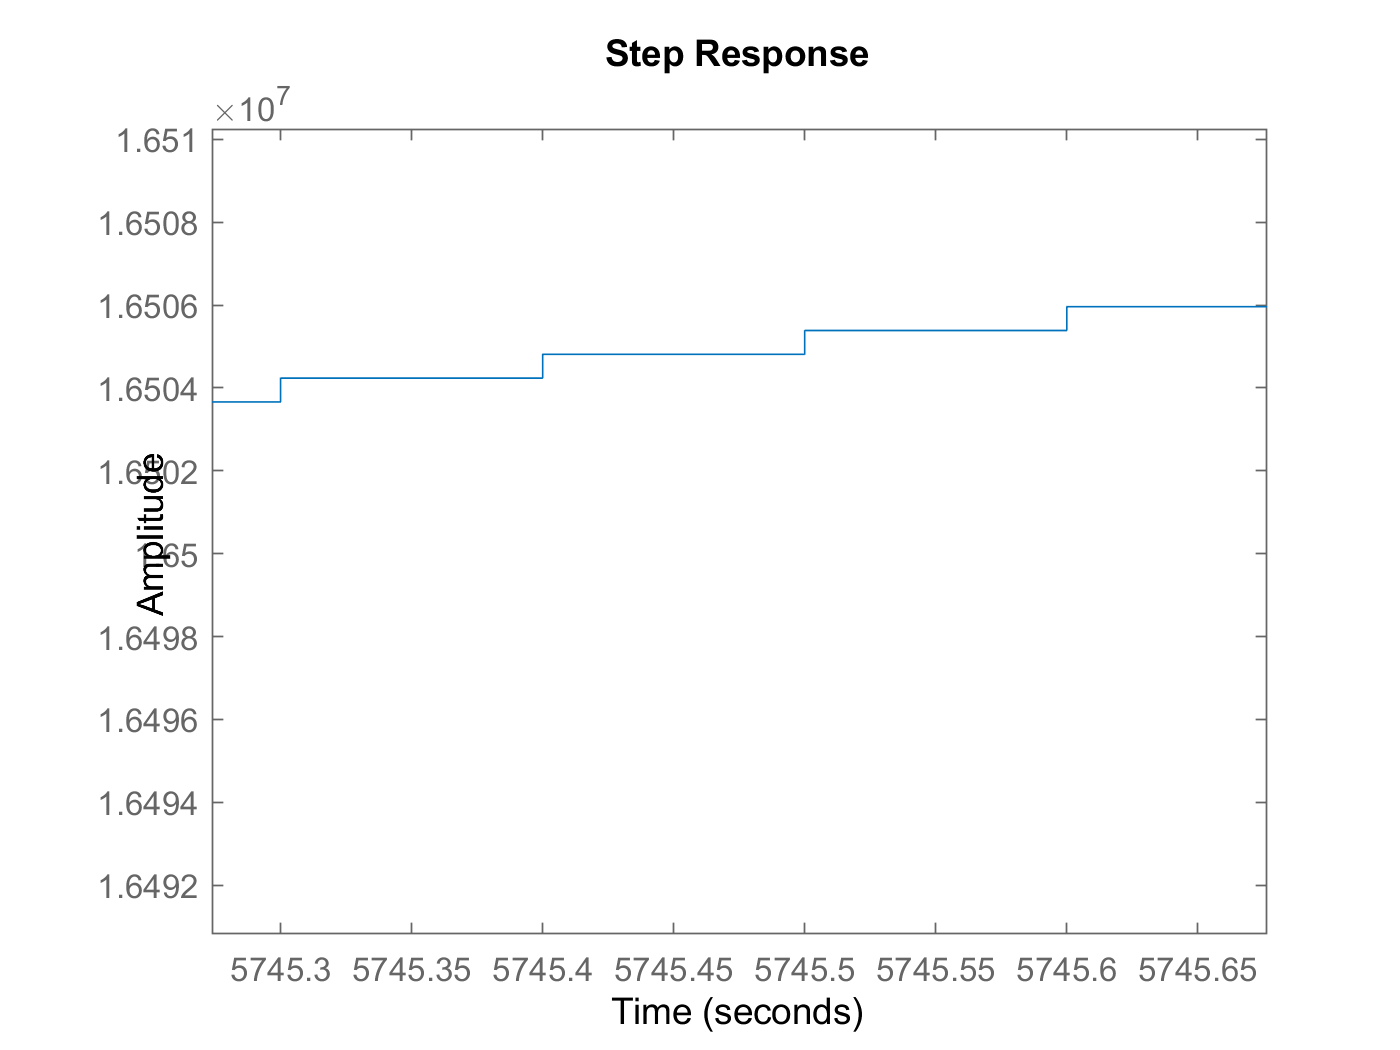

step(sys_d);

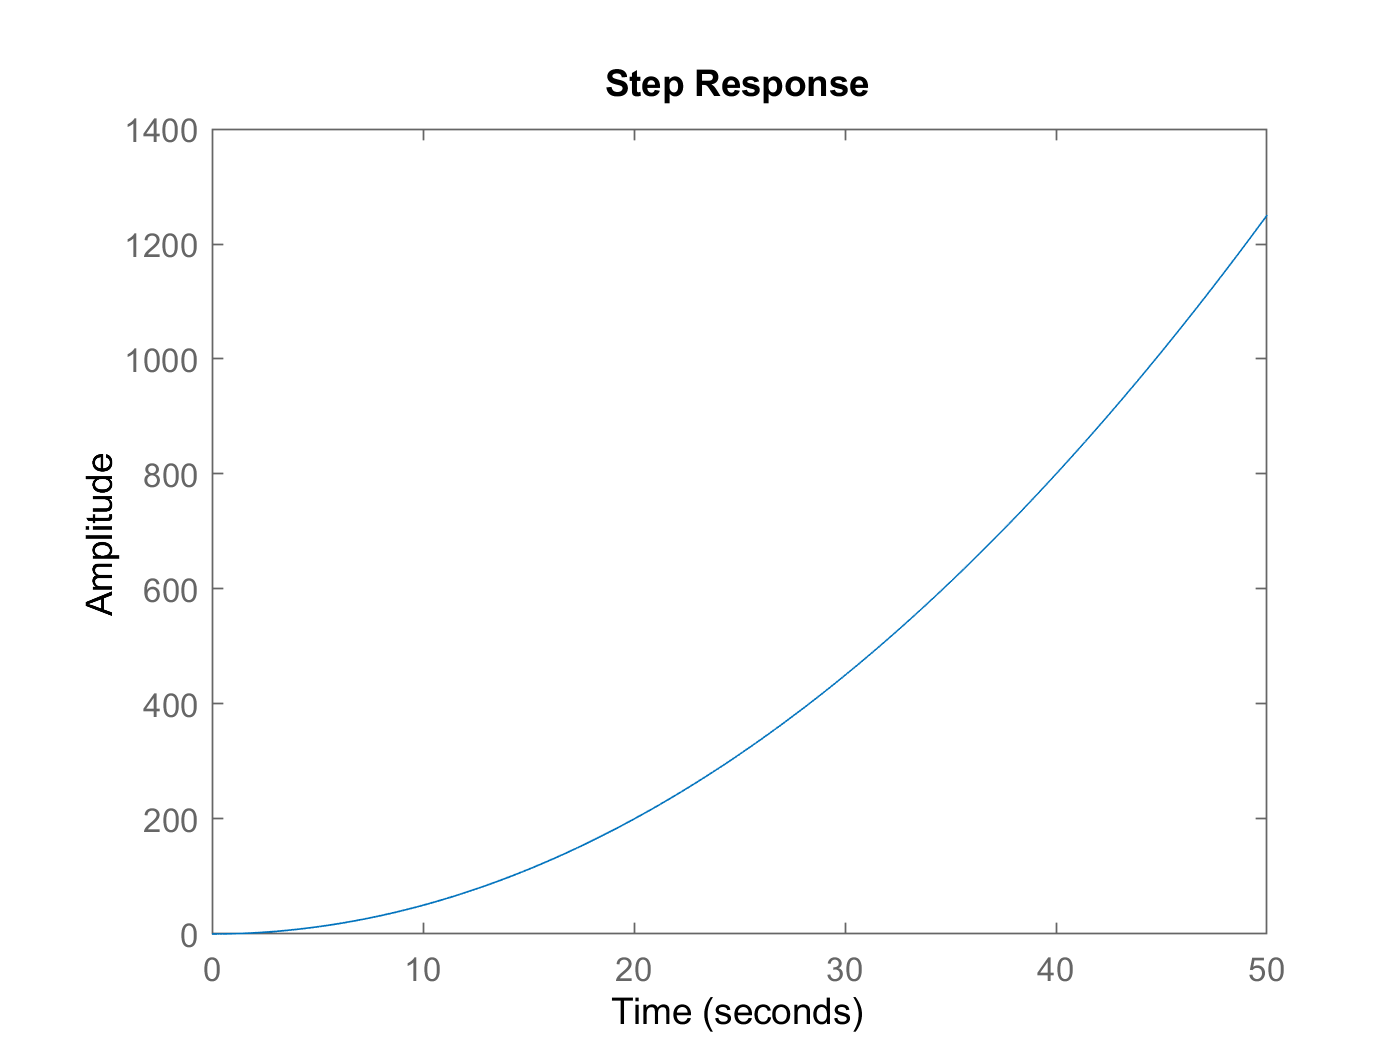

step(sys_ss)

## Closed Loop System

**controllability matrix** C = [B AB A^2B ... A^(n-1)B]

co = ctrb(sys_d); 
Controlability = order(sys_d) == rank(co);
disp("Is controllable? "+Controlability);

Is controllable? true


Choose closed loop discrete system poles

poles= [0.2 0.02];

### Controller Design using Pole Placement

#### Using Direct Substitution

[A_d,B_d,C_d,D_d]= ssdata(sys_d);
K_p= place(A_d,B_d,poles)

K_p =    78.4000   13.8800


x = [0.1;1];
u = -K_p*x

u = -21.7200

for i=1:time
    x = A*x + B*u;
    u = -K_p*x;
    plot_vectorx1(i) = x(1);
    plot_vectorx2(i) = x(2);
    plot_vectoru(i) = u;
end
disp('Closed loop plant response in pole placement method(Direct Substitution)');

Closed loop plant response in pole placement method(Direct Substitution)


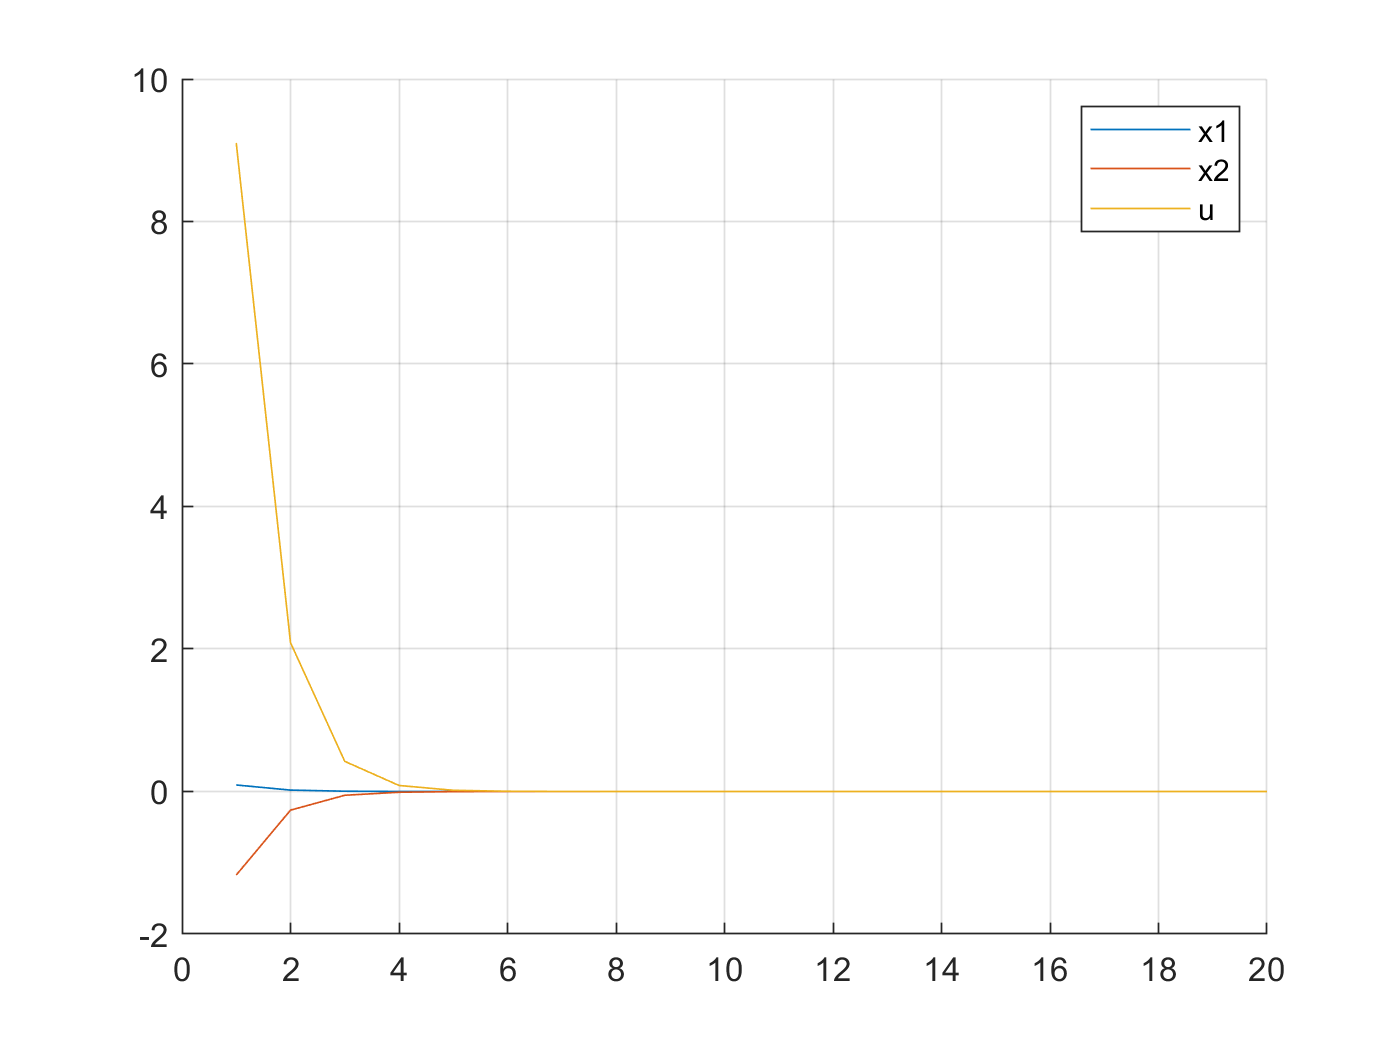

clf
hold on
plot(plot_vectorx1)
plot(plot_vectorx2)
plot(plot_vectoru)
legend({'x1','x2','u'});
grid on
hold off

#### Using Ackermann's Formula

[A_d,B_d,C_d,D_d]= ssdata(sys_d);
K_ack= acker(A_d,B_d,poles)

K_ack =    78.4000   13.8800


x = [0.1;1];
u = -K_ack*x;
for i=1:time
    x = A*x + B*u;
    u = -K_ack*x;
    plot_vectorx1(i) = x(1);
    plot_vectorx2(i) = x(2);
    plot_vectoru(i) = u;
end
disp('Closed loop plant response in pole placement method(Ackermann''s Formula)');

Closed loop plant response in pole placement method(Ackermann's Formula)


clf
hold on
plot(plot_vectorx1)
plot(plot_vectorx2)
plot(plot_vectoru)
legend({'x1','x2','u'});
grid on
hold off

### LQR Controller Design

x[n+1]=Ax[n]+Bu[n] and J = Sum {x'Qx + u'Ru), u* to minimize J/ lqr cost

 Q and R are weight matrices for costs of changes of  x and u respectively

p = 50000;
Q = 1*p*(C'*C);
R = 0.01;
[K,S,CLP] = dlqr(A,B,Q,R)

K =   170.6398   18.4738


S = 	1.0e+04 *

    5.4131    0.0224
    0.0224    0.0013


CLP =    -0.6922
   -0.0084


[xx,kk,ll]=icare(A,B,Q,R)

xx = 	1.0e+03 *

    4.8900    0.0000
    0.0000    0.0020


kk = 	1.0e+03 *

    2.4450    0.0200


ll =    -1.0000
  -11.2250


Create closed loop state space model using matlab func.

sys_cl = ss(A-B*K,B,C,D,Ts)

sys_cl =
 
  A = 
             x1
   x1    0.1468
   x2    -17.06
 
             x2
   x1  0.007631
   x2   -0.8474
 
  B = 
          u1
   x1  0.005
   x2    0.1
 
  C = 
       x1
   y1   1
 
       x2
   y1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



% [A,B,C,D]=ssdata(sys_cl);
x = x0;
u = -K*x;
for i=1:time
    x = A*x + B*u;
    u = -K*x;
    plot_vectorx1(i) = x(1);
    plot_vectorx2(i) = x(2);
    plot_vectoru(i) = u;
end
disp('Closed loop plant response in LQR');

Closed loop plant response in LQR


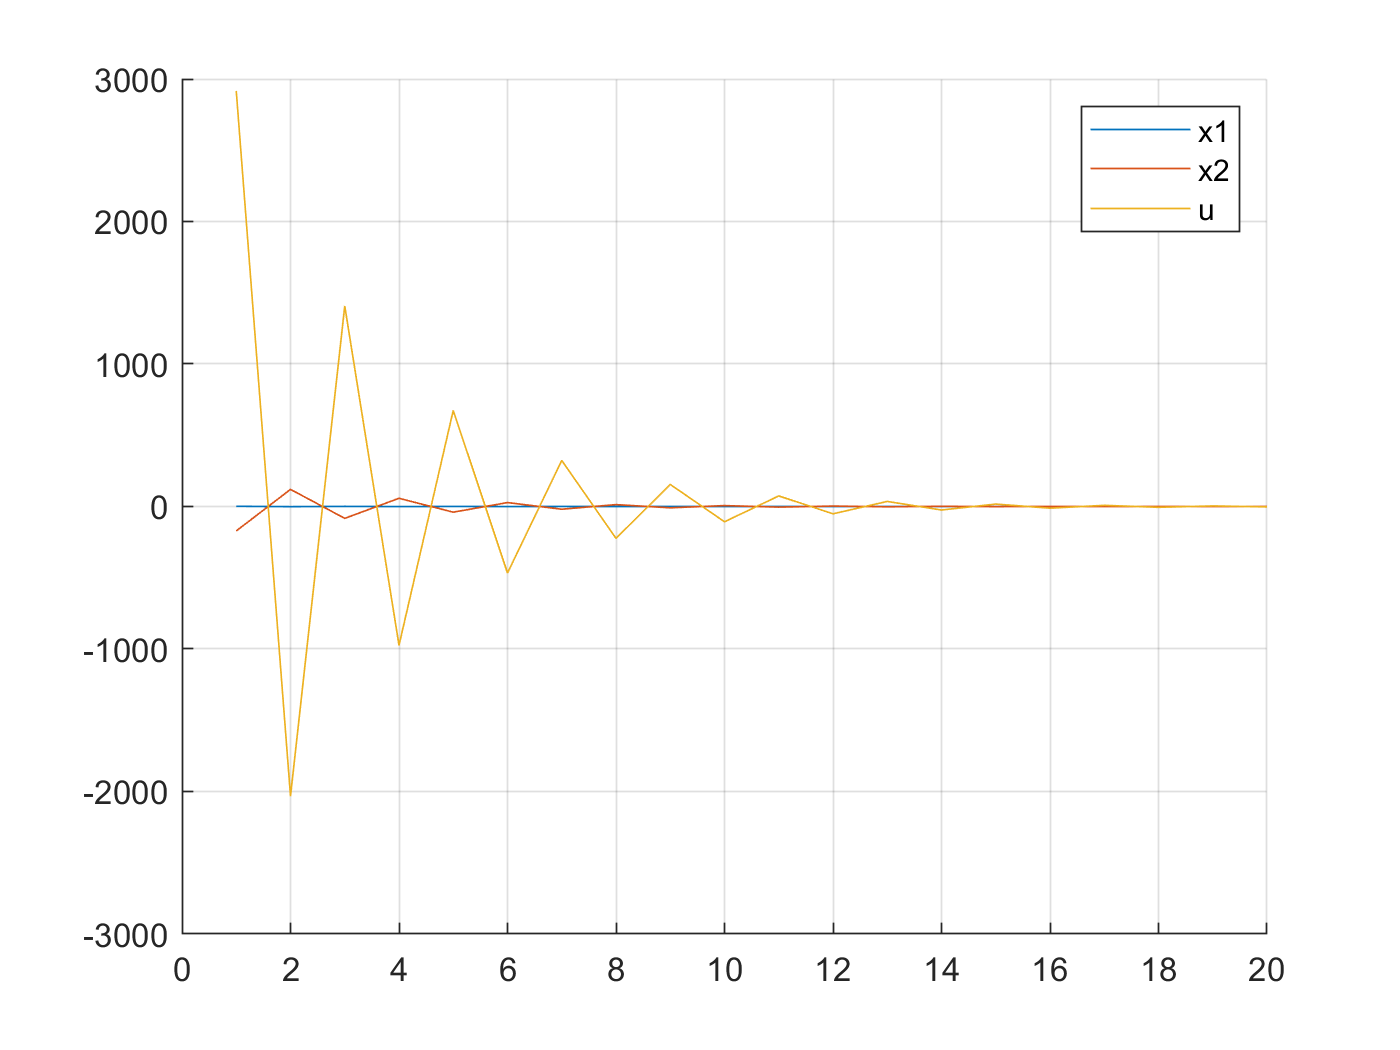

clf
figure(1)
hold on
plot(plot_vectorx1)
plot(plot_vectorx2)
plot(plot_vectoru)
legend({'x1','x2','u'});
grid on
hold off

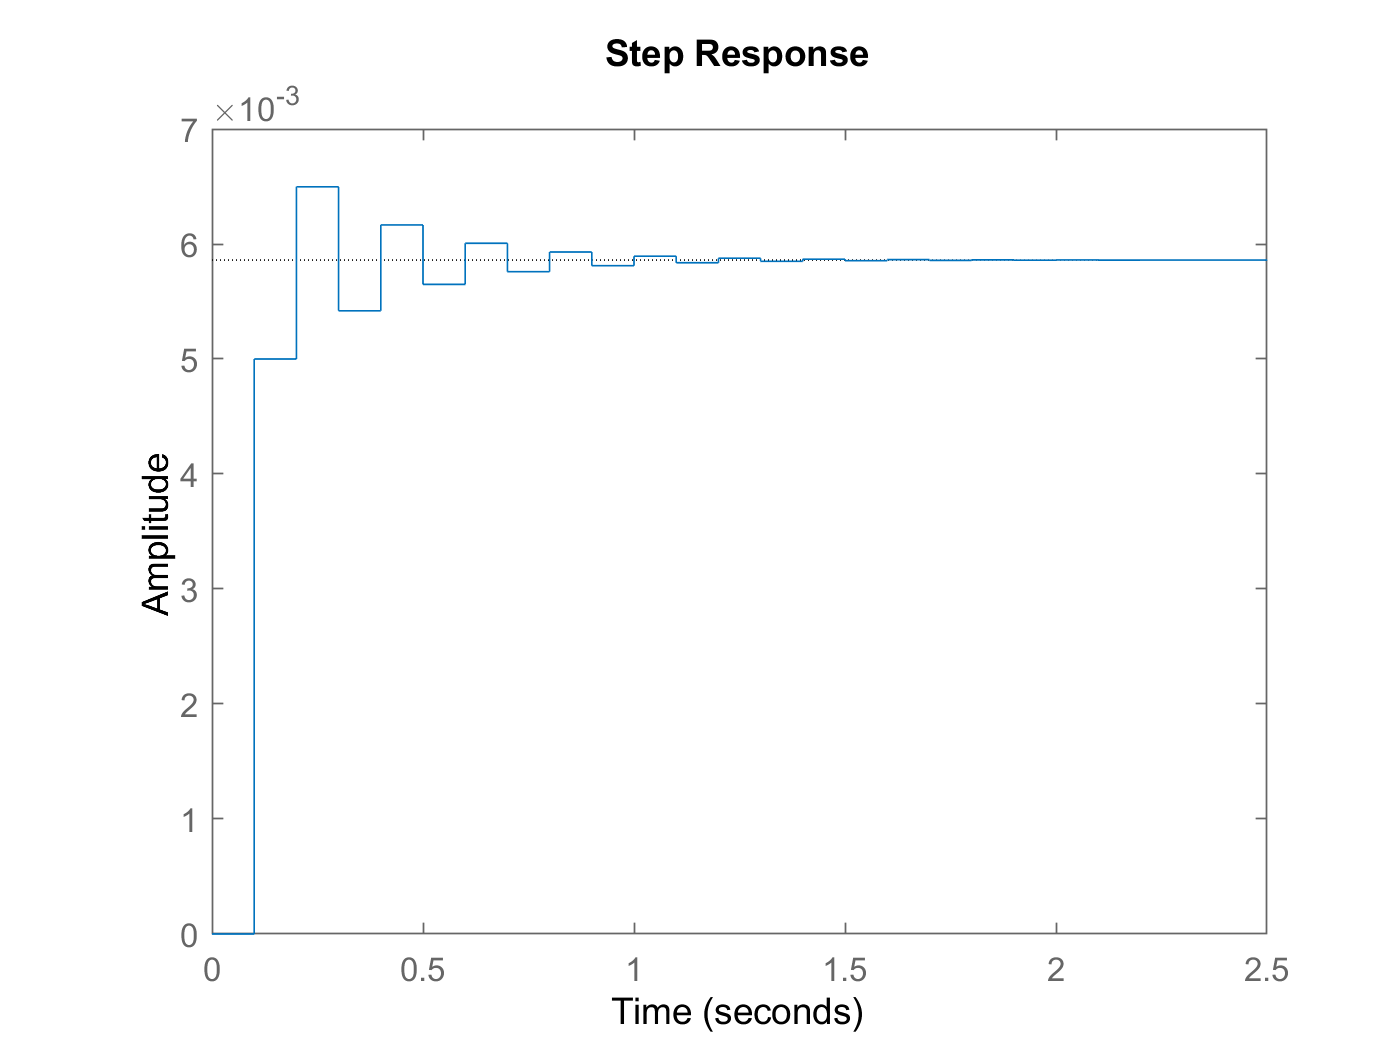

step(sys_cl);

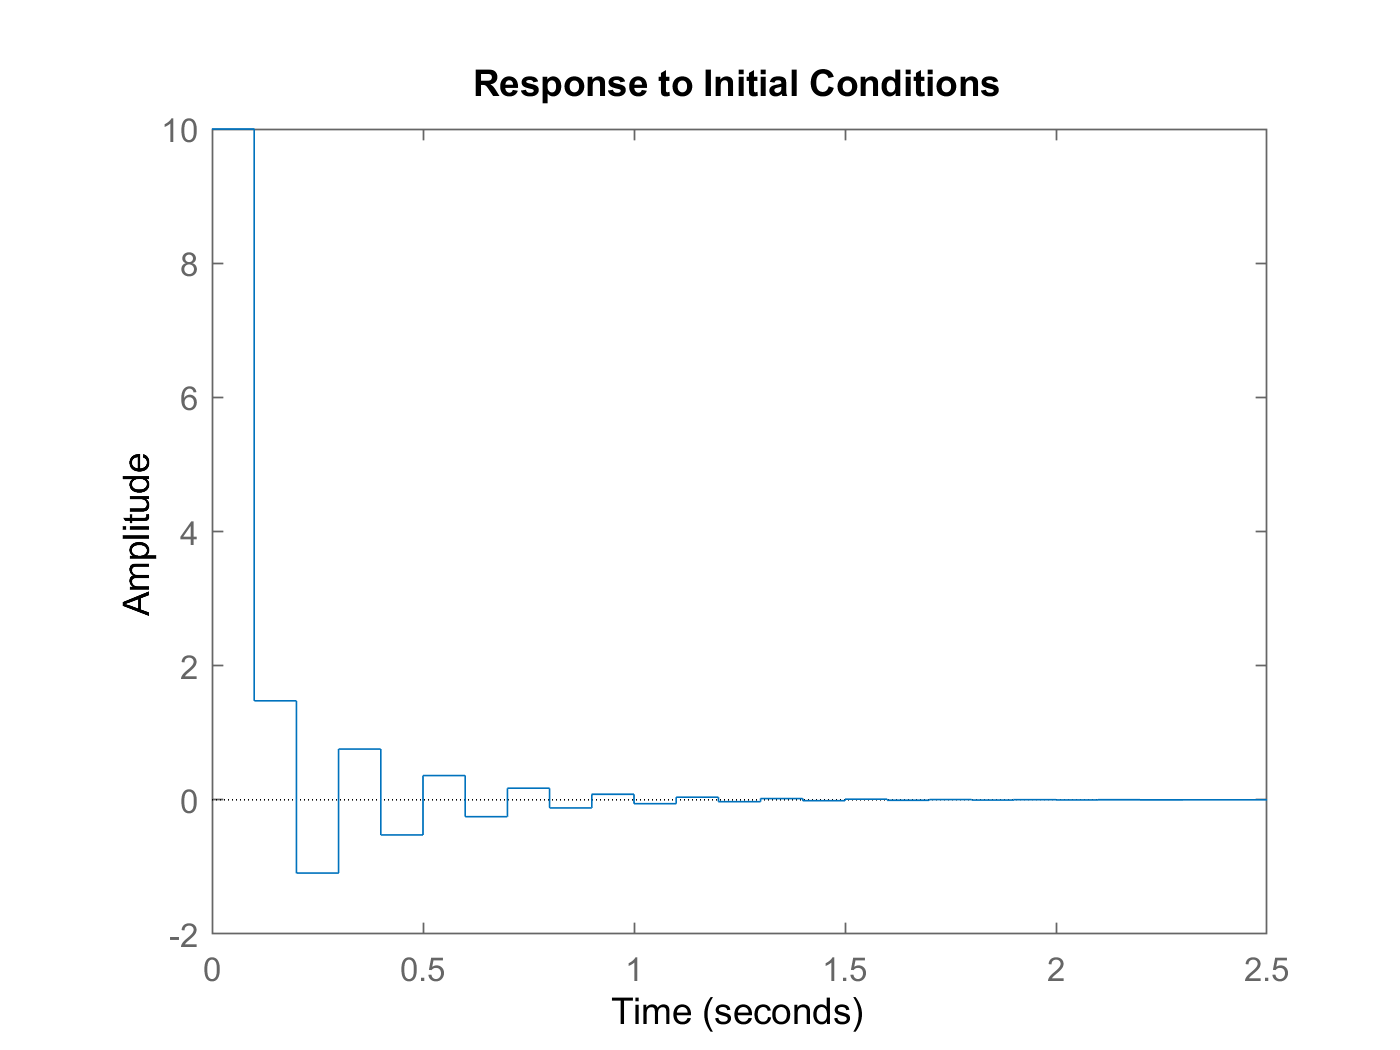

initial(sys_cl,x0)

Simulation using matlab function

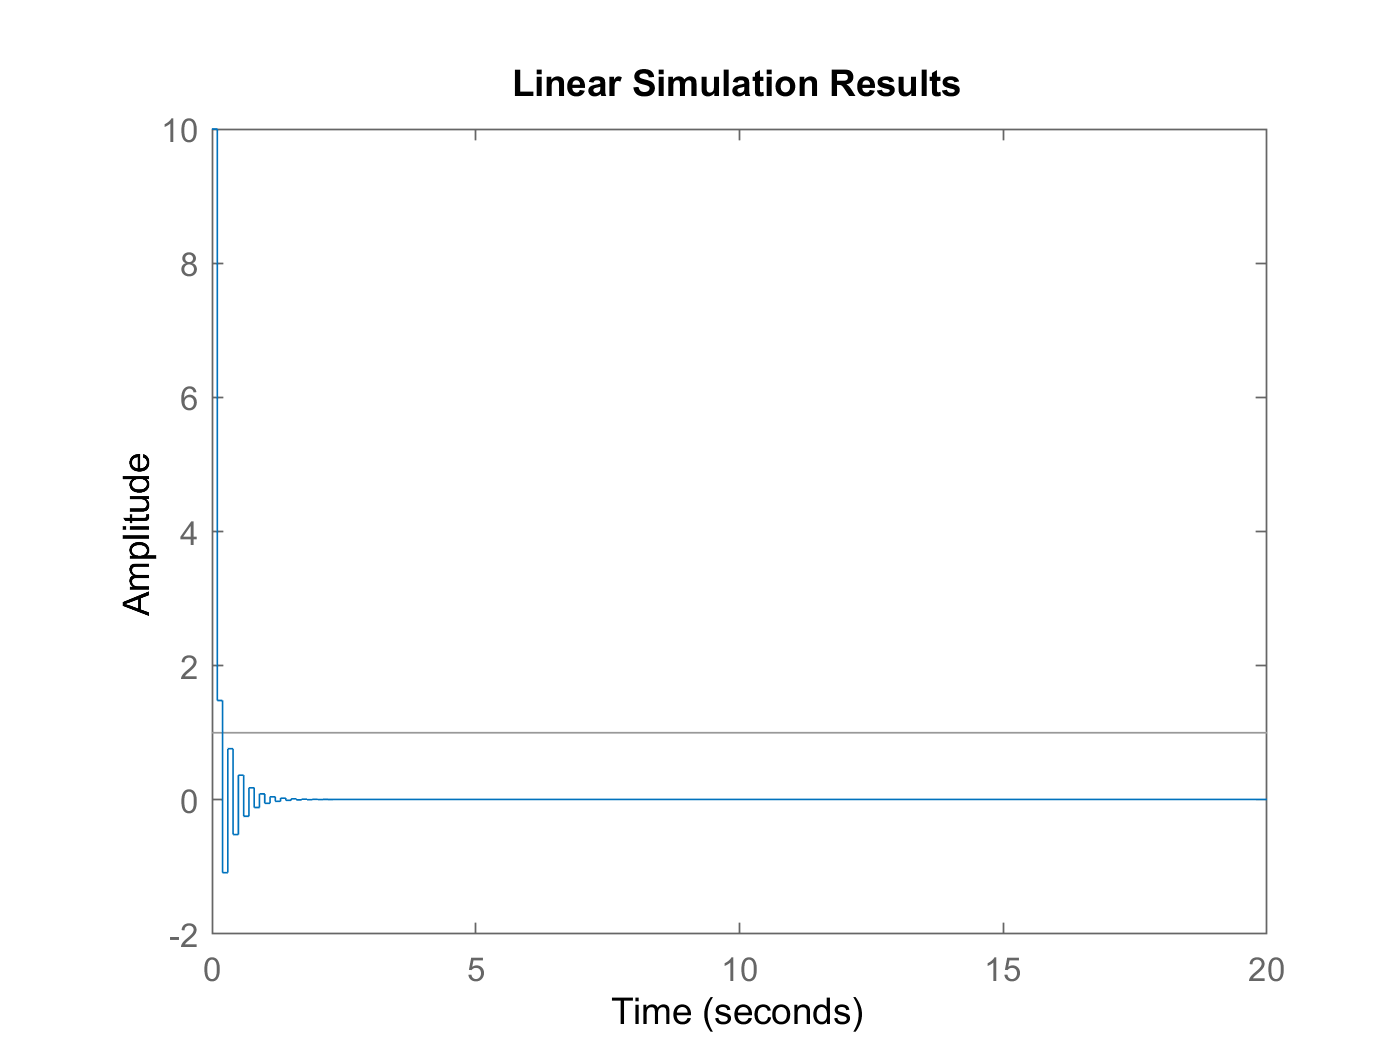

t=0:Ts:time;
reference = 1*ones(size(t));
lsim(sys_cl,reference,t,x0);

## Estimator Unit Design

***observability matrix ***O = [C AC AC^2 ... AC^(n-1)]'

ob = obsv(sys_d); 
observability = rank(ob) == order(sys_d);
disp("Is observable? "+observability)

Is observable? true


### Kalman Gain Calculation

QN, RN are process error and measurement error covariance matrices

QN = 500;
RN = 0.01*eye(1);
[kalmf,L,P,M] = kalmd(sys_ss,QN,RN,Ts);
% [kest,L,P] = kalman(sys_cl,QN,RN);
L

L =     1.6575
    7.7875


time = 20;
x = [0.1;1];
z = [0;0];
u = -K*z;

plot_vectorx1hat=zeros(1,time);
plot_vectorx2hat=zeros(1,time);

for i=1:time
    r = C*x-C*z;
    z = A*z + B*u + L*r;
    x = A*x + B*u;    
    u = -K*z;
    plot_vectorx1(i) = x(1);
    plot_vectorx1hat(i) = z(1);
    plot_vectorx2(i) = x(2);
    plot_vectorx2hat(i) = z(2);
end
disp('Closed loop plant response using Observer');

Closed loop plant response using Observer


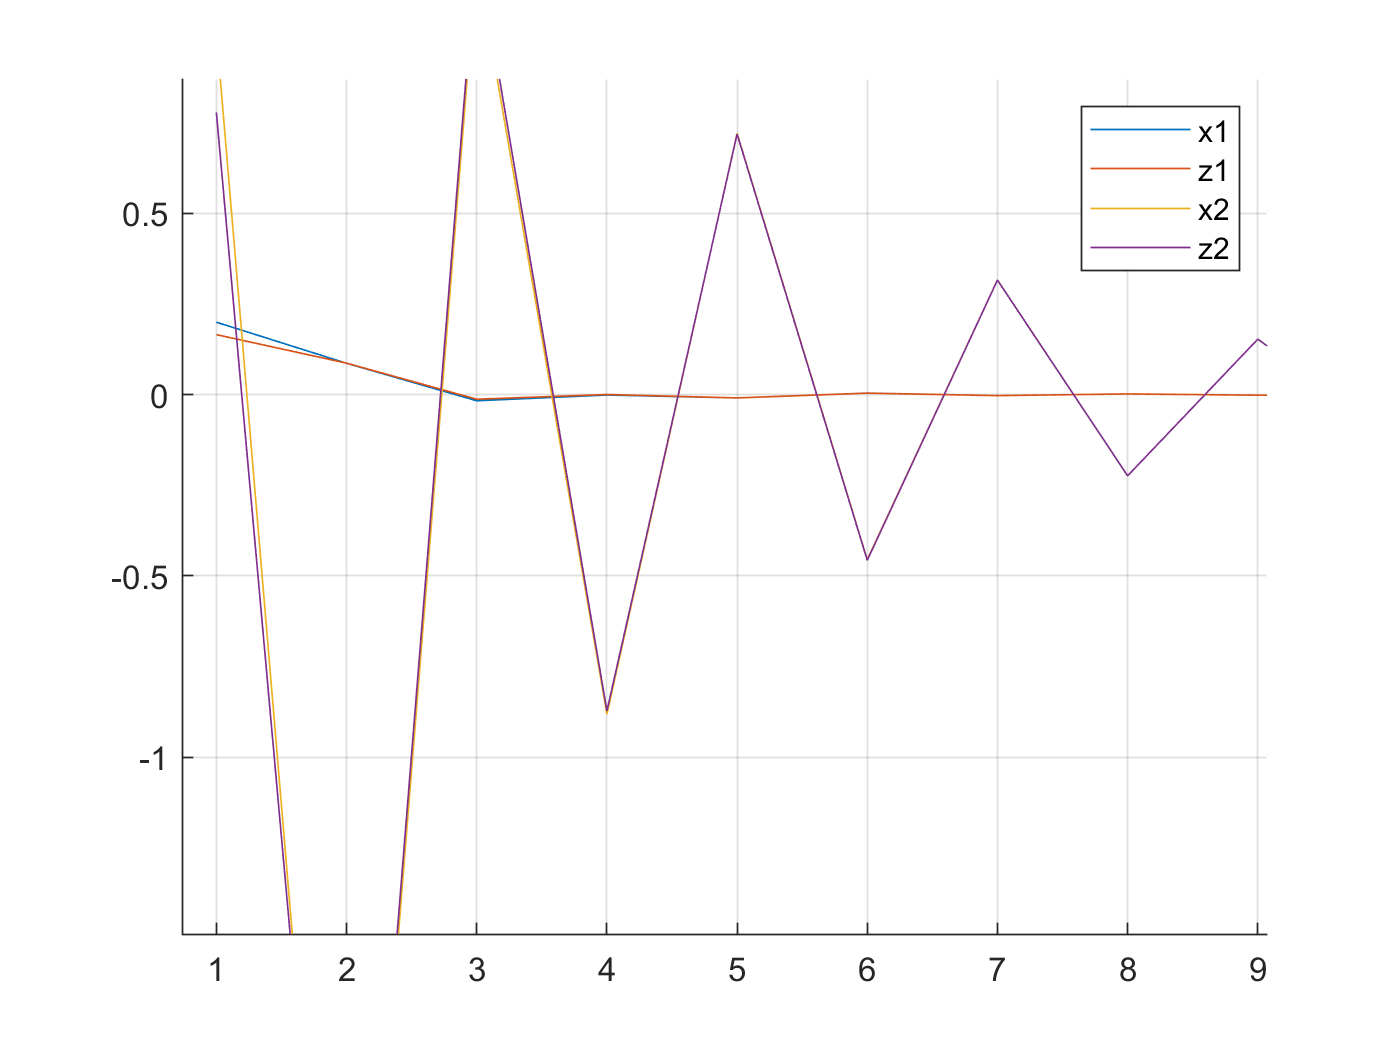

clf
hold on
plot(plot_vectorx1)
plot(plot_vectorx1hat)
plot(plot_vectorx2)
plot(plot_vectorx2hat)
legend({'x1','z1','x2','z2'});
grid on
hold off

## Lyapunov function Calculation

#### V (x) = x'P x, dV/dt (x) < 0, A'P + P A < − Q, Q > 0

Q=25;


### solves A'P + P A = − Q, might not yeild a unique, positive definite solution

P_lyap=lyap(A,Q*eye(2));
disp("is P_lyap positive definite? eigenvalues of P_lyap");

is P_lyap positive definite? eigenvalues of P_lyap


eig(P_lyap)

ans =   -13.1570
  -11.9055


### solving the inequality i.e. A'P + P A < − Q , P > 0

setlmis([]);
P=lmivar(1,[size(A,1),1]);
lmi_id=1; 	
lmiterm([lmi_id 1 1 P],-Q,1);           % LMI # 1, element @ (1,1): -P
lmiterm([lmi_id 1 2 -P],A',1);          % LMI # 1, element @ (1,2) : A'*P
lmiterm([lmi_id 2 1 P],1,A);            % LMI # 1, element @ (2,1) : P*A
lmiterm([lmi_id 2 2 P],-1,1);           % LMI # 1, element @ (2,2): -P 
lmiterm([-lmi_id 1 1 P],1,1);           % LMI # 2  P       for P > 0
lmisys = getlmis;                         % Create the LMI system
[tmin,rP_feas] = feasp(lmisys) ;          % Solve LMI


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                       -0.022228

 Result:  best value of t:    -0.022228
          f-radius saturation:  0.000% of R =  1.00e+09
 



P = dec2mat(lmisys,rP_feas,P);            % display P matrix
disp("is P positive definite? eigenvalues of P");

is P positive definite? eigenvalues of P


eig(P)

ans =     0.0411
    0.0412


plot_vectorx = [plot_vectorx1;plot_vectorx2];

### plotting evaluated V (t) = x(t)'P x(t) against time

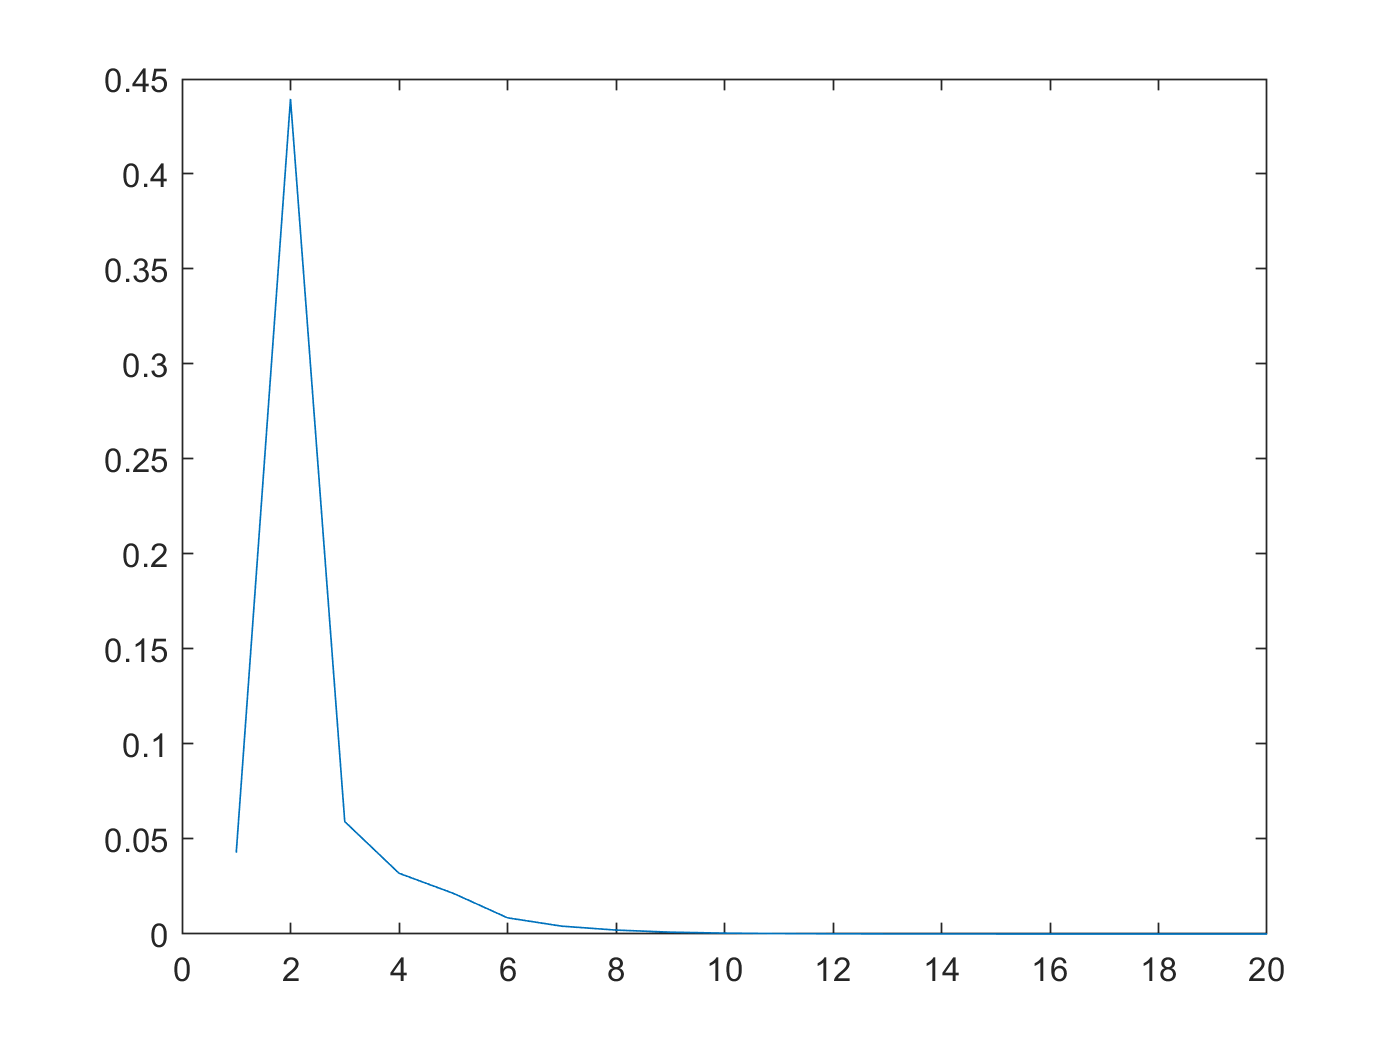

for i= 1:time
    V(i) = plot_vectorx(:,i)'*P*plot_vectorx(:,i);
end

figure(2)
plot(1:time,V);

### plotting V (x) = x'P x, x= [x1;x2] against the states

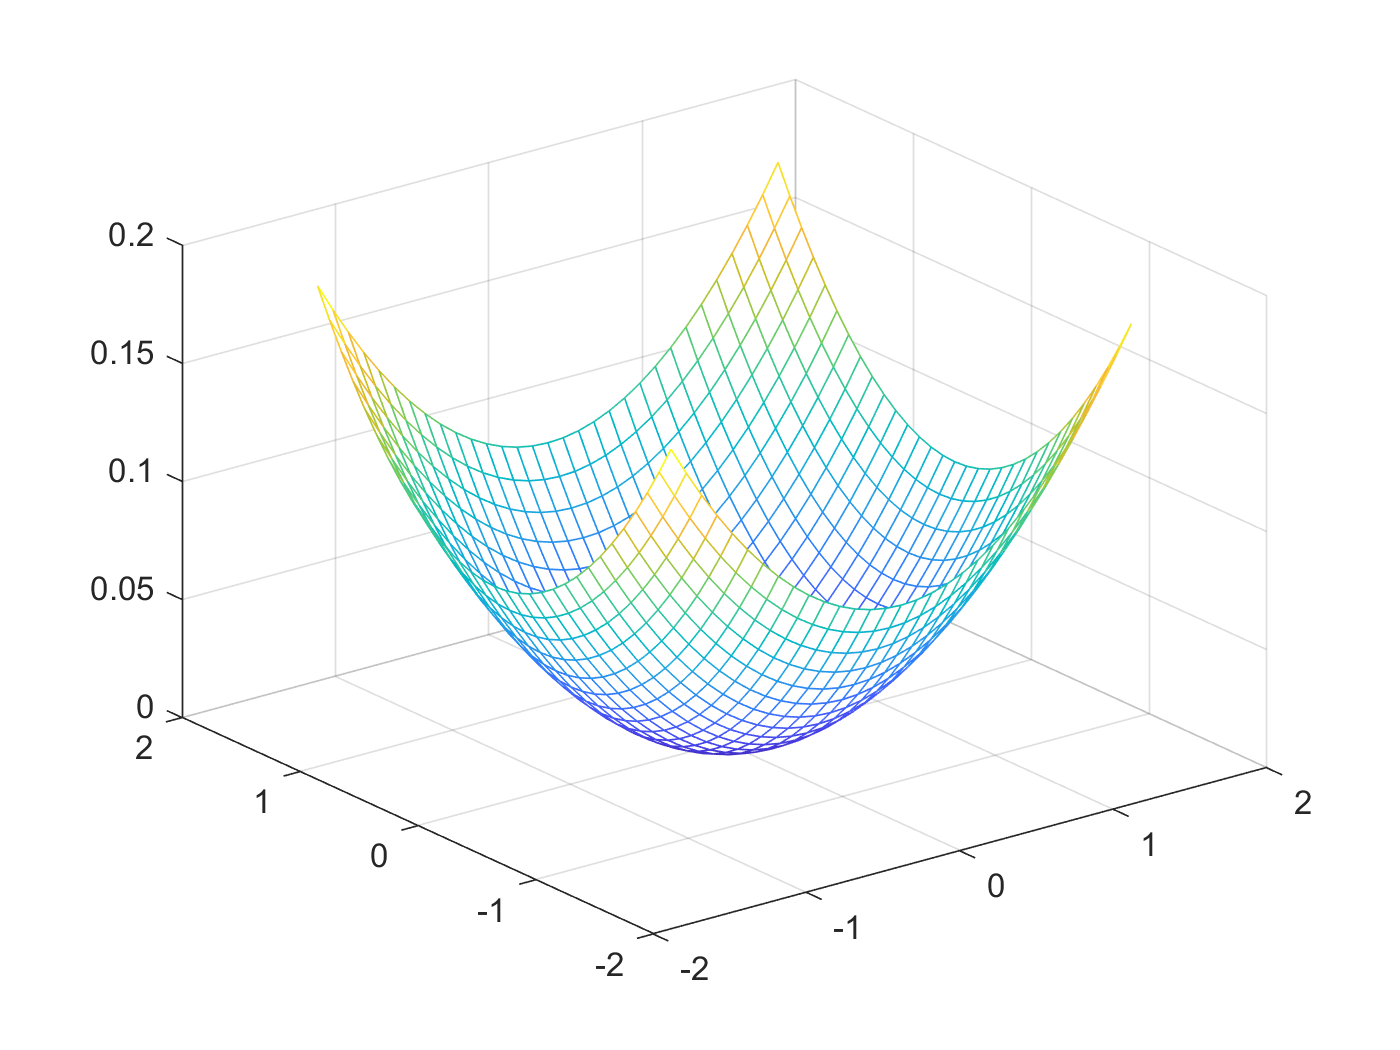

x1= [-1.5:0.1:1.5];
x2= [-1.5:0.1:1.5];
[X,Y]= meshgrid(x1,x2);
z= X.*(X.*P(1,1)+Y.*P(2,1))+(X.*P(1,2)+Y.*P(2,2)).*Y;
figure(3);
mesh(X,Y,z)